# Sets pump curves.

### This example contains: 

- Load a network. 

- Computed Hydraulic & Quality Time Series via ENepanet binary file. 

- Plot pressures. 

- Get head curve. 

- Set new head curve values. 

- Computed hydraulics. 

- Unload library.

### Clear - Start Toolkit

clear; close('all'); clc;
start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


### Load a network.

d = epanet('Net1.inp');

EPANET version {20200} loaded (EMT version {v2.2.003}).
Loading File "Net1.inp"...
Input File "Net1.inp" loaded sucessfuly.


### Computed Hydraulic & Quality Time Series via ENepanet binary file.

Results = d.getComputedTimeSeries;

nodeID = '10';
indexNode = d.getNodeIndex(nodeID);

### Plot pressures.

figure;
subplot(2,1,1);
plot(Results.Time, Results.Pressure(:,indexNode));
title('Before set curve');
xlabel('Time (hrs)'); 
ylabel(['Pressure (', d.NodePressureUnits,')'])  

### Get head curve.

headCurve = d.getLinkPumpHeadCurveIndex;

### Set new head curve values.

d.setCurve(headCurve,[2000 250]); 
pumpIndex = d.getLinkPumpIndex

pumpIndex =     13


d.getCurveIndex

ans = int32
   1


d.setLinkPumpHeadCurveIndex(pumpIndex, headCurve)

ans =      1


### Computed hydraulics.

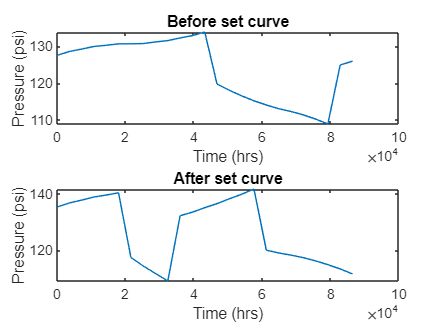

Results = d.getComputedTimeSeries;  
subplot(2,1,2);
plot(Results.Time, Results.Pressure(:,indexNode));
title('After set curve');
xlabel('Time (hrs)'); 
ylabel(['Pressure (', d.NodePressureUnits,')'])

### Unload library.

d.unload

EPANET Class is unloaded
